clear all, close all
t= 0:0.5:200;

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


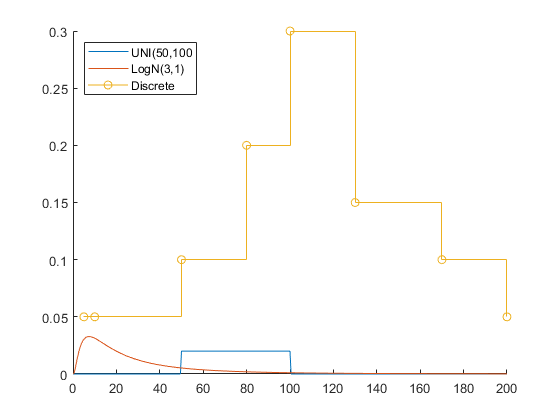

mon_val = [5 10 50 80 100 130 170 200];
pd1 = makedist('Uniform','lower',50,'upper',100);
cdf1 = cdf(pd1,t);
pd2 = makedist('Lognormal','mu',3,'sigma',1);
cdf2 = cdf(pd2,t);
pdf3 = [ 0.05 0.05 0.1 0.2 0.3 0.15 0.1 0.05];
cdf3 = cumsum(pdf3);

figure
hold on
plot(t,pdf(pd1,t),'-')
plot(t,pdf(pd2,t),'-')
stairs(mon_val, pdf3, '-o')
legend('UNI(50,100', 'LogN(3,1)', 'Discrete', 'Location', 'NW')

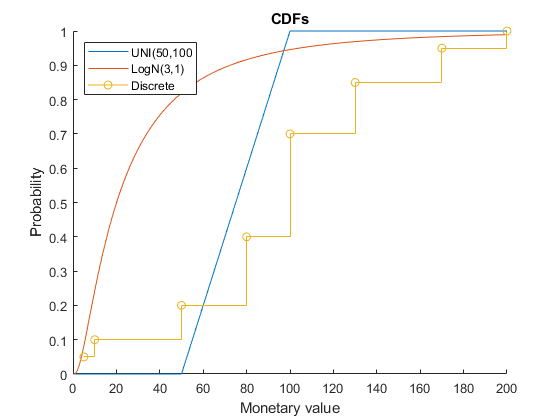


figure 
hold on
plot(t, cdf1, '-')
plot(t, cdf2, '-')
stairs(mon_val, cdf3, '-o')
title('CDFs')
ylabel('Probability')
xlabel('Monetary value')
legend('UNI(50,100', 'LogN(3,1)', 'Discrete', 'Location', 'NW')